% Generate VHTSIGA by wlanVHTSIGA(cfgVHT)
cfgVHT = wlanVHTConfig;
cfgVHT.ChannelBandwidth = 'CBW20';
cfgVHT.MCS= 8;
[y,bits] = wlanLSIG(cfgVHT);

## Encoding

% BCC Encoder
bcc_encodedData = wlanBCCEncode(bits,'1/2');
size(bcc_encodedData)

ans =     48     1


% BCC Interleaver
number_CBPSSI = 48; % number of coded bits per OFDM symbol per spatial stream per interleaver block
cbw = 'CBW20';
out = wlanBCCInterleave(bcc_encodedData,'Non-HT',number_CBPSSI,cbw);
size(out)

ans =     48     1


% Constellation Mapper 
numBPSCS = 1; % Number of coded bits per subcarrier per spatial stream
phase = 0; % BPSK and QBPSK
mappedData = wlanConstellationMap(out,numBPSCS,phase);

% scatterplot(mappedData(:,1))
% scatterplot(mappedData(:,2))

% Pilot Insertion
out_insert=[mappedData(1:5,1);1;mappedData(6:18,1);1;mappedData(19:30,1);1;mappedData(31:43,1);-1;mappedData(44:48,1)];

% The unpopulated bits are 0
out_full = [zeros(6,1);out_insert(1:26);0;out_insert(27:52);zeros(5,1)];

k = -32:1:31;
k =  k' ;

ifft = zeros(64,1);

% IFFT 
for nn = 1:64       
        yy = out_full .* exp(j*2*pi*k*(nn-1)/64);
        ifft(nn) = (1/sqrt(52)) * sum(yy) ;
end

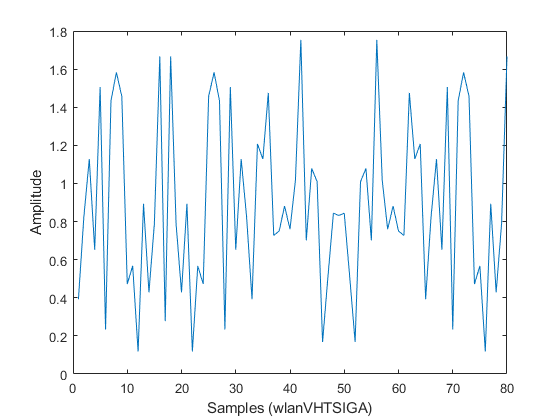

% Add CP
out_cp = [ifft(49:64);ifft(1:64)];


plot(abs(y))
xlabel('Samples (wlanVHTSIGA)')
ylabel('Amplitude')

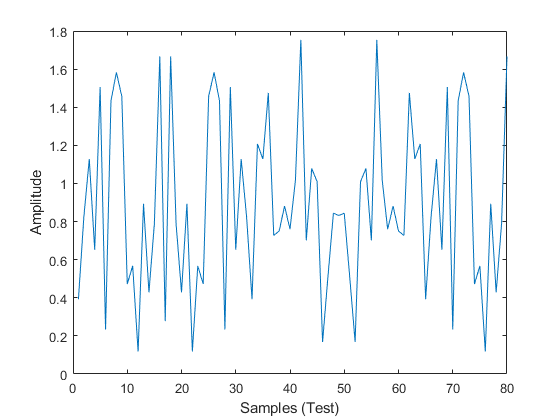


% hold on
plot(abs(out_cp))
xlabel('Samples (Test)')
ylabel('Amplitude')

## Decoding

% FFT
recx = out_cp(17:80);

k2 = 1:1:64;
k2 = k2';
STFfft = zeros(64,1);

for kk = 1:64       
        yy =  sqrt(52) *recx .* exp(-j*2*pi*(kk-33)*(k2-1)/64);
        STFfft(kk) = 1/64 *  sum(yy) ;
end

% Extract 48 data bits
BF_mod = [STFfft(7:11);STFfft(13:25);STFfft(27:32);STFfft(34:39);STFfft(41:53);STFfft(55:59)];

% Constellation Demapper 
% numBPSCS = 1; % Number of coded bits per subcarrier per spatial stream
% phase = [0 pi/2]; % BPSK and QBPSK
% noiseVar = 0;
demappedData = wlanConstellationDemap(BF_mod,0,numBPSCS,phase);
demappedBits = (demappedData<=0);

% BCC Deinterleaver
number_CBPSSI = 48; % number of coded bits per OFDM symbol per spatial stream per interleaver block
cbw = 'CBW20';

full_demap = double(demappedBits);

% isequal(out,full_demap)

deinterleave = wlanBCCDeinterleave(full_demap,'Non-HT',number_CBPSSI,cbw);
size(deinterleave)

ans =     48     1


isequal(bcc_encodedData,deinterleave)

ans = logical
   1


% BCC Decoder
tDepth = 24;
bcc_deCodedData = wlanBCCDecode(deinterleave,'1/2','hard',tDepth);
size(bcc_deCodedData)

ans =     24     1


isequal(bcc_deCodedData,bits)

ans = logical
   1
